This script provides a basic ILC implementation to introduce the concept.  Let's take a simple 1st order plant and try to improve our tracking to a sinusoidal.

P = tf(1,[1 1]);
T = 0.1;
Pd = c2d(P,T);

I need to wrap a feedback controller around this to stabilize the system - I'll just use a proportional controller for simplicity.

K = 0.5;

Firstly, let me see the error for a standard feedback controller.

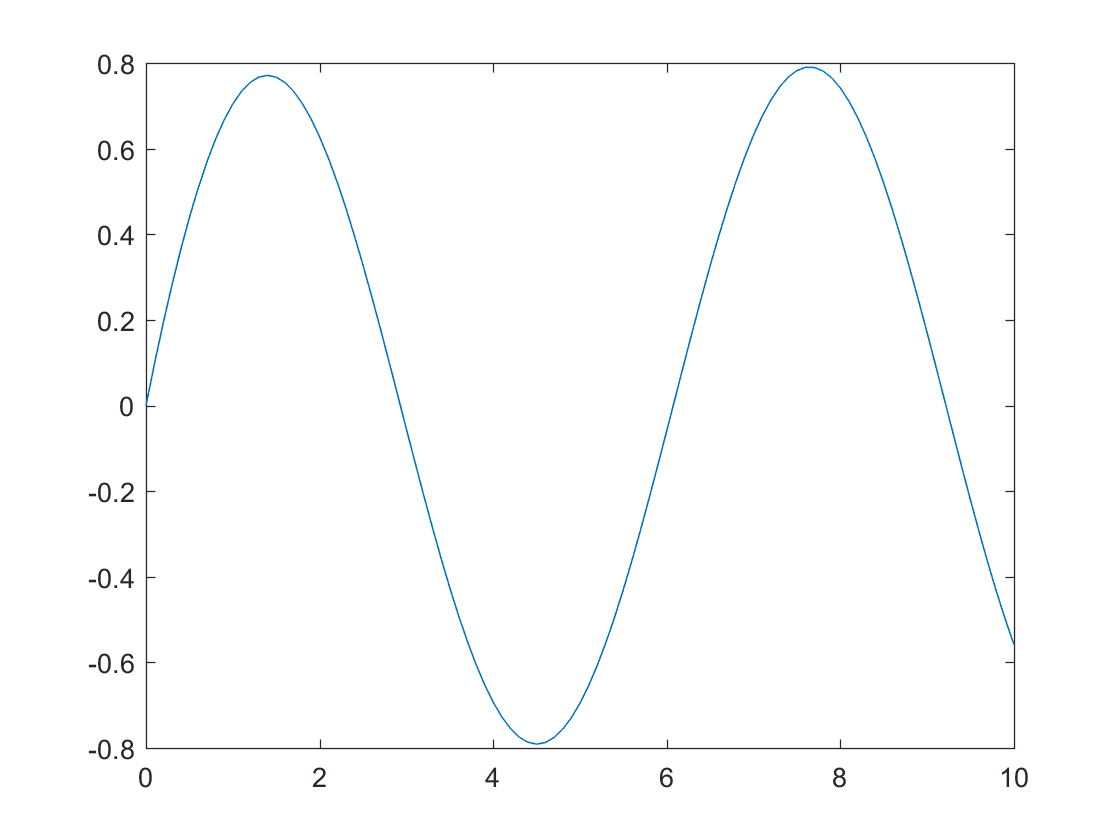

u_ilc = [[0:T:10]' zeros(101,1)];
sim('ILC_Intro');
plot(Response(:,1),Response(:,2)-Response(:,3))

I propose a simple (and very common) ILC update law here: $u_{j+1}(k) = u_j(k)+\alpha e_{j}(k+1) $.  We can then look at the performance as $\alpha$ varies. 

For starters, let's evaluate the learning gain stability.

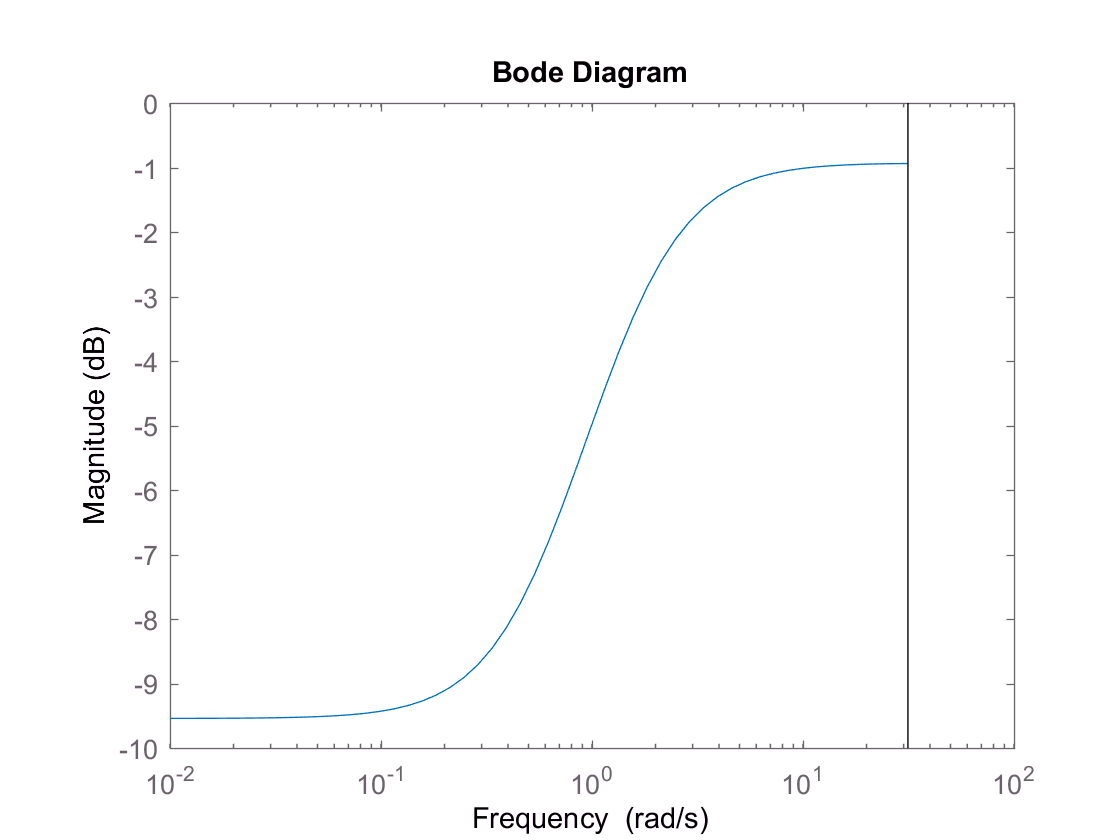

Plant = Pd*(1-feedback(Pd*K,1));
z = tf('z',T);
alpha = 2;
bodemag(1-z*alpha*Plant)

Hnorm = norm(1-z*alpha*Plant,'inf')

Hnorm = 0.8975

It looks like a learning gain of about 2.5 is allowable.

u_ilc = [[0:T:10]' zeros(101,1)];
N = 50;  %Number of iterations of ILC

Now let's run ILC using the Simulink model.

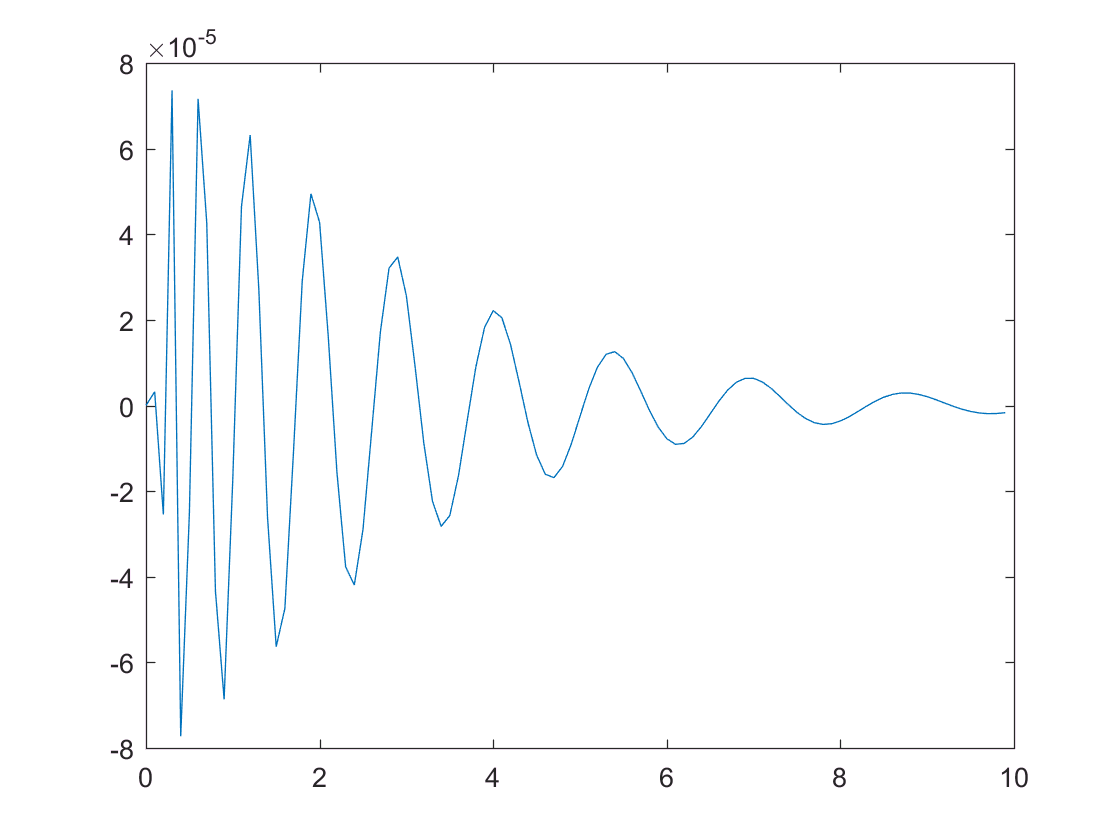

e = [];
for ii = 1:N
    sim('ILC_Intro');  %Get the data
    e = [e;std(Response(1:end-1,2)-Response(1:end-1,3))];  %Record error value
    for ii = 1:100
        u_ilc(ii,2) = u_ilc(ii,2)+alpha*(Response(ii+1,2)-Response(ii+1,3));  %Implement ILC
    end
end
plot(Response(1:end-1,1),Response(1:end-1,2)-Response(1:end-1,3))

It seems like it might be working!  Now let's plot the error convergence.

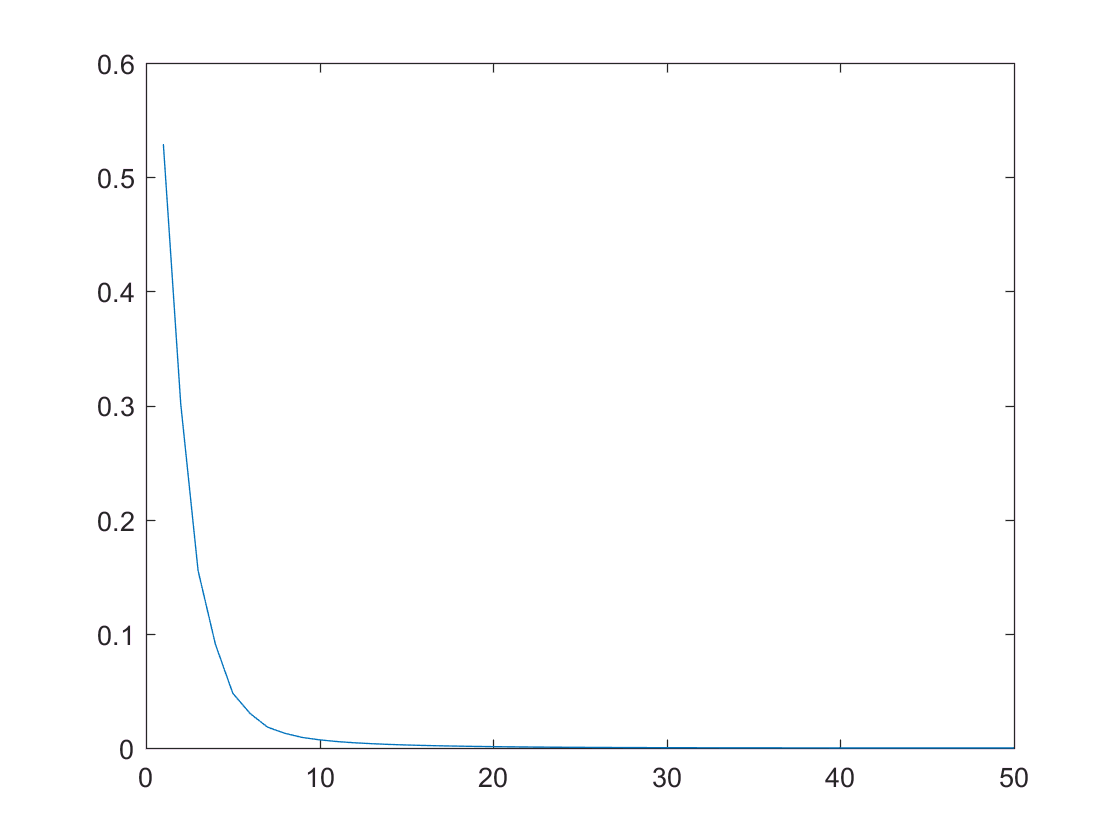

plot(e)

Now let's take a more systematic view of the ILC convergence.  The generalized plant for $H_\infty$ synthesis is

G_inf = [1 1;-z*Plant 0];

Now I'll just use the standard synthesis command in Matlab.  I realize for many of you this is new, but a detailed explanation is outside the scope of this course.

[L,CL,gam] = hinfsyn(G_inf,1,1);

Now let's run this digital filter to see what happens.  To start with I need to convert the model to "DSP" form for the filtering operation.  This is a somewhat onerous set of steps, but the basic idea is that the filter command wants the transfer function as a ratio of polynomials in $z^{-1}$, not the $z$'s we have in the standard transfer function.

L = tf(L);  %Convert to TF
[num,den] = tfdata(L,'v');  %Extract polynomials
L_DSP = filt(num,den,T);  %Convert to polynomials in z^{-1}
[b,a] = tfdata(L_DSP,'v');  %Rip out the new polynomials for the filt command.

Now it's time to test the performance!

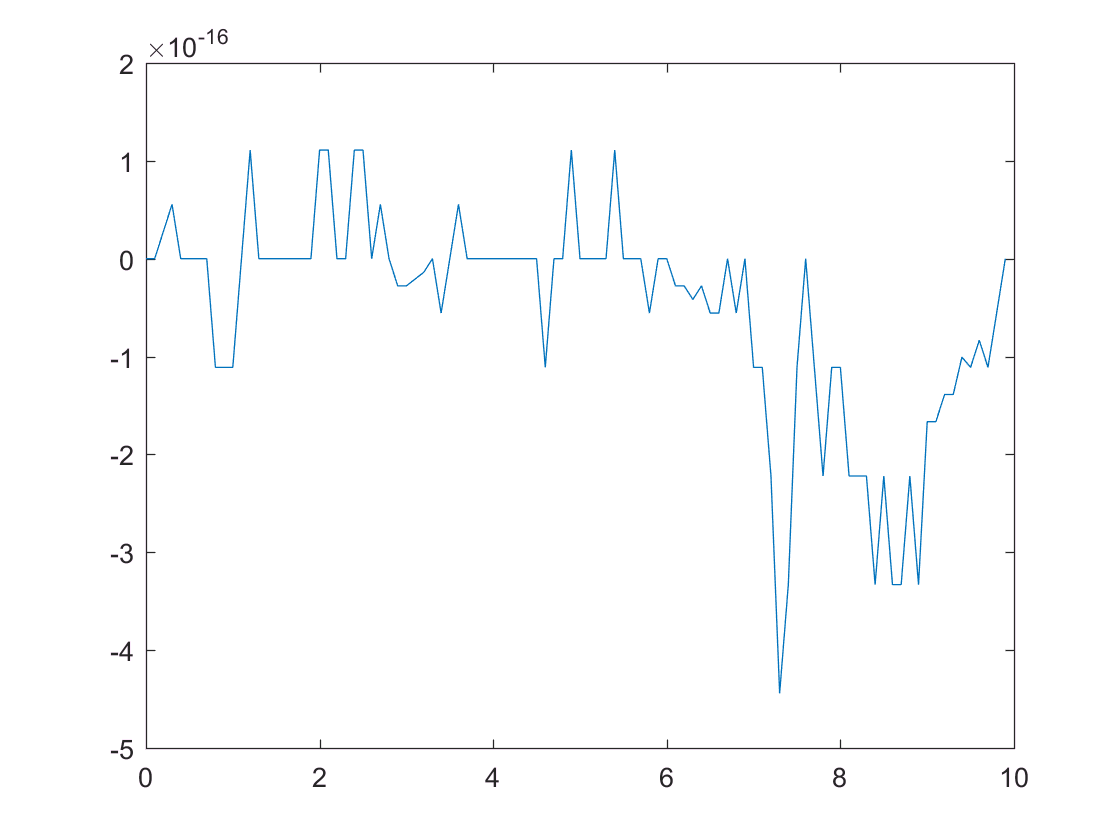

u_ilc = [[0:T:10]' zeros(101,1)];  %Reset the ILC
e = [];
for ii = 1:N
    sim('ILC_Intro');  %Get the data
    e = [e;std(Response(1:end-1,2)-Response(1:end-1,3))];  %Record error value
    Le = filter(b,a,Response(:,2)-Response(:,3));  %This performs the filtering - implements L
    for ii = 1:100
        u_ilc(ii,2) = u_ilc(ii,2)+Le(ii+1);  %Implement ILC
    end
end
plot(Response(1:end-1,1),Response(1:end-1,2)-Response(1:end-1,3))

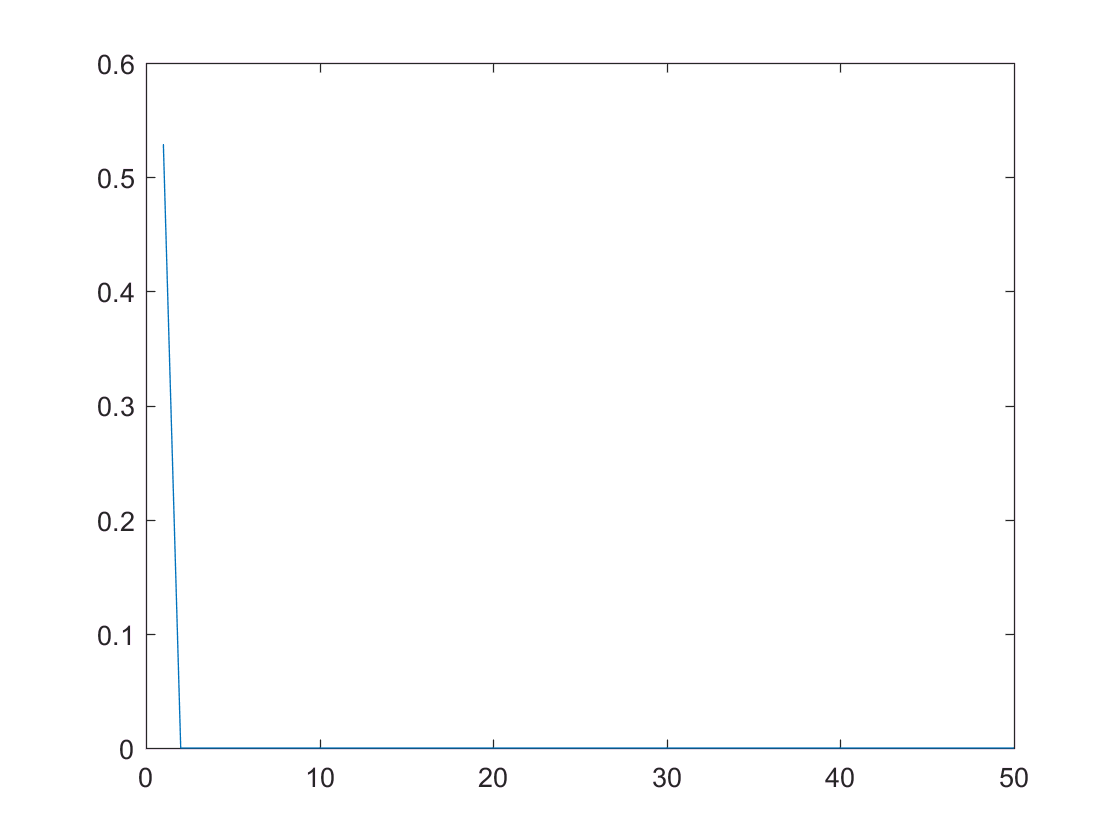

plot(e)

This is MUCH better, and is no longer ad-hoc!  For those of you who have seen $H_\infty$ control before this is yet another application; for those of you who have not, it's probably magical but hopefully you can leverage the code at least to apply to other systems.